clear
cylindricalGeometry = batteryCylindricalGeometry();

cylindricalGeometry.Radius = simscape.Value(0.0105,"m");
cylindricalGeometry.Height = simscape.Value(0.07,"m");

cylindricalCell = batteryCell(cylindricalGeometry);

disp(cylindricalCell)

  Cell with properties:

            Geometry: [1×1 simscape.battery.builder.CylindricalGeometry]
    CellModelOptions: [1×1 simscape.battery.builder.CellModelBlock]
                Mass: 0.1000 (kg)
            Capacity: 5 (A*hr)
              Energy: 50 (W*hr)

Show all properties



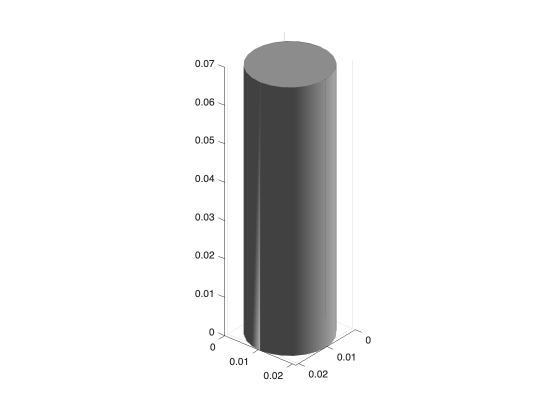

f2 = uifigure("Color","white");
cylindricalCellchart = batteryChart(f2,cylindricalCell);

cylindricalCell.CellModelOptions.BlockParameters.thermal_port="model";

parallelAssembly = batteryParallelAssembly(cylindricalCell,48,Topology="Square",Rows = 4,InterCellGap=simscape.Value(0.01,"m"));

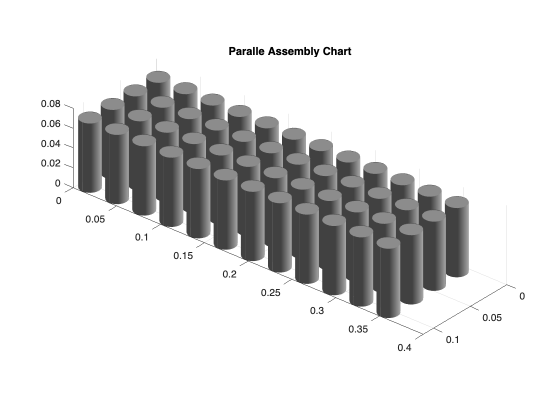

f = uifigure("Color","white");
parallelAssemblyChart = batteryChart(f,parallelAssembly);
title(parallelAssemblyChart,"Paralle Assembly Chart")

disp(parallelAssembly.PackagingVolume)

    0.0029 (m^3)



disp(parallelAssembly.CumulativeMass)

    4.8000 (kg)



module = batteryModule(parallelAssembly,4,StackingAxis="X",InterParallelAssemblyGap=simscape.Value(0.001,"m"));

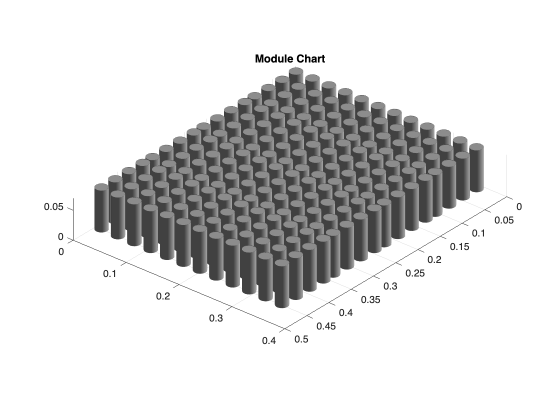

f = uifigure("Color","white");
moduleChart = batteryChart(f,module);
title(moduleChart,"Module Chart")

disp(module.PackagingVolume)

    0.0116 (m^3)



disp(module.CumulativeMass)

   19.2000 (kg)



disp(module.PackagingVolume)

    0.0116 (m^3)



Visualize Battrey ModuleAssembly Object

moduleAssembly = batteryModuleAssembly(repmat(module, 1,2),StackingAxis = "Y",InterModuleGap = simscape.Value(0.005,"m"),CircuitConnection="Series" );

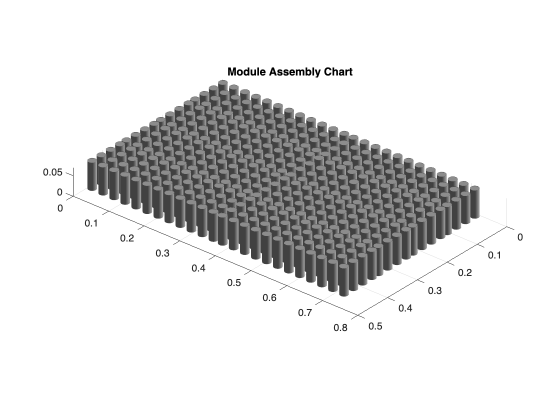

f = uifigure("Color","white");
moduleAssemblyChart = batteryChart(f,moduleAssembly);
title(moduleAssemblyChart,"Module Assembly Chart")

disp(moduleAssembly.Module(1).Name);

Module1


disp(moduleAssembly.Module(2).Name);

Module2


moduleAssembly.Module(1).Name="ModuleA";
moduleAssembly.Module(2).Name="ModuleB";

to stack the moudle along z axiz no. of levels or tires should be defined in ModuleAssembly

zSatckedModule = batteryModuleAssembly(repmat(module,1,4),StackingAxis="Y",NumLevels=2,InterModuleGap=simscape.Value(0.05,"m"));

visulaiziing the module assembly

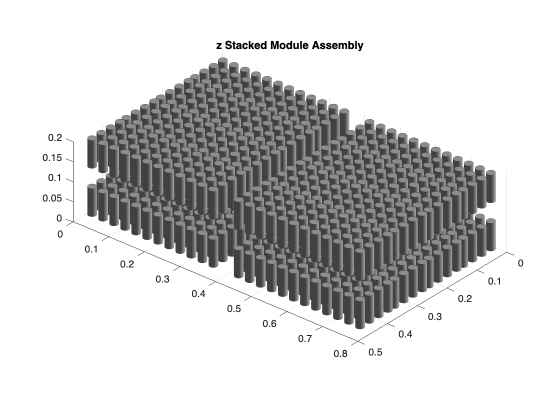

f = uifigure("Color","white");
zStackedModuleAssemblyChart = batteryChart(f,zSatckedModule);
title(zStackedModuleAssemblyChart,"z Stacked Module Assembly")

Resolution of battery objects

The `ParallelAssembly` and `Module` objects have a `ModelResolution` property that allows you to set the level of fidelity of the generated Simscape model used in simulations. You can specify the `ModelResolution` property to either:

- `Lumped` — Lowest fidelity. The battery object uses only one electrical model. To obtain the fastest compilation time and running time, use this value.

- `Detailed` — Highest fidelity. The battery object uses one electrical model and one thermal model for each battery cell.

- `Grouped` — Custom simulation strategy, available only to `Module` objects.

it can be viewed in battery chart by SimulationStratergyView On

lumpedParallelAssembly= batteryParallelAssembly(cylindricalCell,48,Rows = 4,InterCellGap=simscape.Value(0.005,"m"));

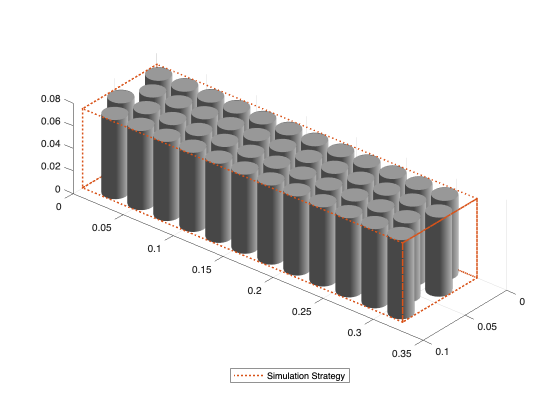

f = uifigure("Color","white");
lumpedParallelAssemblyChart=batteryChart(f,lumpedParallelAssembly,SimulationStrategyVisible="on");

For detailed Model Resolution in parallel Assembly

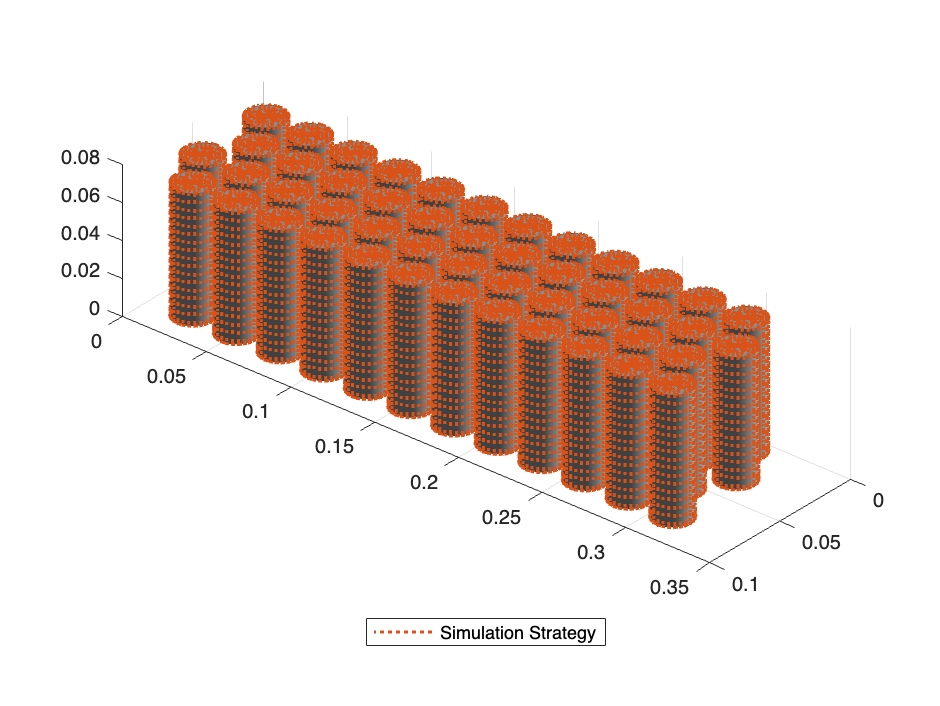

detailedParallelAssemblyChart =   BatteryChart with properties:

   Battery:
                             Battery: [1×1 simscape.battery.builder.ParallelAssembly]

   Simulation Strategy:
           SimulationStrategyVisible: on
         SimulationStrategyLineColor: [0.8500 0.3250 0.0980]
         SimulationStrategyLineStyle: ":"
         SimulationStrategyLineWidth: 1.5000

   Thermal Management Strategy:
    ThermalManagementStrategyVisible: off

   Axes Properties:
                         AxesVisible: on
                            AxesXDir: "normal"
                            AxesYDir: "normal"
                            AxesZDir: "normal"

   Light Properties:
                          LightColor: [1 1 1]
                          LightStyle: "infinite"
                       LightPosition: [-1 1 1]
                        LightVisible: on

   General:
                              

detailedParallelAssembly = lumpedParallelAssembly;
detailedParallelAssembly.ModelResolution = "Detailed";
f = uifigure("Color","white");
detailedParallelAssemblyChart=batteryChart(detailedParallelAssembly,SimulationStrategyVisible="on")

For module

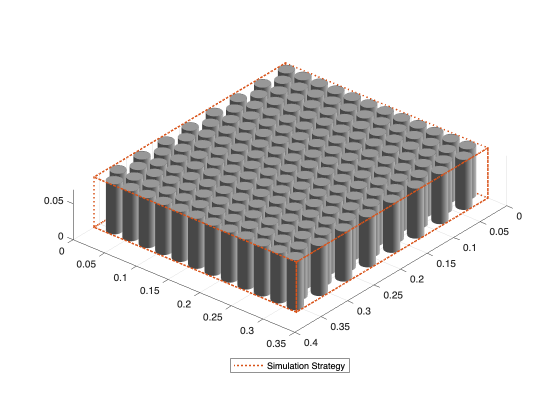

lumpedModuleChart =   BatteryChart with properties:

   Battery:
                             Battery: [1×1 simscape.battery.builder.Module]

   Simulation Strategy:
           SimulationStrategyVisible: on
         SimulationStrategyLineColor: [0.8500 0.3250 0.0980]
         SimulationStrategyLineStyle: ":"
         SimulationStrategyLineWidth: 1.5000

   Thermal Management Strategy:
    ThermalManagementStrategyVisible: off

   Axes Properties:
                         AxesVisible: on
                            AxesXDir: "normal"
                            AxesYDir: "normal"
                            AxesZDir: "normal"

   Light Properties:
                          LightColor: [1 1 1]
                          LightStyle: "infinite"
                       LightPosition: [-1 1 1]
                        LightVisible: on

   General:
                              Parent: [1×1 Figure]
 

lumpedModule = batteryModule(lumpedParallelAssembly , 4, StackingAxis="X",InterParallelAssemblyGap=simscape.Value(0.005,"m"));
f = uifigure("Color","white");
lumpedModuleChart = batteryChart(f,lumpedModule,SimulationStrategyVisible="on")

lumpedModule.AmbientThermalPath = "CellBasedThermalResistance";

datailedModule = lumpedModule;
detailedModule.ParallelAssembly.ModelResolution = "Detailed"

detailedModule = struct with fields:
    ParallelAssembly: [1×1 struct]
     ModelResolution: "Detailed"


detailedModule.ModelResolution = "Detailed";


for adding thermal coolent add it to the bottom

by using CoolingPlate Property to bottom

lumpedModule.CoolingPlate = "Bottom";

lumpedModuleAssembly = batteryModuleAssembly(repmat(lumpedModule,1,4),StackingAxis="X",InterModuleGap=simscape.Value(0.005,"m"));

Making a pack of Lumped module

lumpedPack = batteryPack(repmat(lumpedModuleAssembly,1,4),StackingAxis="X",InterModuleAssemblyGap=simscape.Value(0.005,"m"));

f = uifigure("Color","white");
lumpedBatterypackChart = batteryChart(f,lumpedPack,SimulationStrategyVisible="on");
title(lumpedBatterypackChart,"lumped battery pack");

building simscape model for the battery

buildBattery(lumpedModule,LibraryName="Dummy_cylindrical_Pack")

The directory /Users/manindersingh/Documents/MATLAB/project/+Dummy_cylindrical_Pack already exists. Specify a different library name or build directory. To keep the existing name, delete the existing directory by running the command rmdir("/Users/manindersingh/Documents/MATLAB/project/+Dummy_cylindrical_Pack","s").